MTL_Path = "/Users/Ashlynn/Desktop/Summer 2020/Honours-ECE579a/Code/Datasets/Canada/montreal-air-quality.csv"; 
TO_Path = "/Users/Ashlynn/Desktop/Summer 2020/Honours-ECE579a/Code/Datasets/Canada/toronto-dt-air-quality.csv"; 

MTL_AQ_Table = AQ_table(MTL_Path);
TO_AQ_Table = AQ_table(TO_Path);

[MTL_AQ_Table, TO_AQ_Table] = same_dates(MTL_AQ_Table, TO_AQ_Table)

max_len = 2171

MTL_AQ_Table = 2145×7 table
       date        pm25    o3     no2    so2    co     AQ 
    ___________    ____    ___    ___    ___    ___    ___

    06-Jul-2020     17     NaN    NaN    NaN    NaN     17
    05-Jul-2020     18      11      4    NaN    NaN     18
    04-Jul-2020     38      24      6      7      6     38
    03-Jul-2020     47      26      6      8      6     47
    02-Jul-2020     38      19      9    NaN    NaN     38
    01-Jul-2020     35      28      8      6    NaN     35
    30-Jun-2020     52      20      5      5    NaN     52
    29-Jun-2020     46      22      7      5      6     46
    28-Jun-2020     33      29      8      5      6     33
    27-Jun-2020     24      29      5      5      6     29
    26-Jun-2020     17   

TO_AQ_Table = 2145×7 table
       date        pm25    o3     no2    so2    co     AQ 
    ___________    ____    ___    ___    ___    ___    ___

    06-Jul-2020     45     NaN    NaN    NaN    NaN     45
    05-Jul-2020     33      18      8    NaN    NaN     33
    04-Jul-2020     26      26      4    NaN      1     26
    03-Jul-2020     49      27      6    NaN      1     49
    02-Jul-2020     39      25      7    NaN      2     39
    01-Jul-2020     20      41     11    NaN      2     41
    30-Jun-2020     32      27      7    NaN      1     32
    29-Jun-2020     30      40     10    NaN      2     40
    28-Jun-2020     27      25      5    NaN      2     27
    27-Jun-2020     38      34      5      1      1     38
    26-Jun-2020     35    


% Claculating the daily difference between AQ in TO and MTL 
% Positive value indicates higher value in TO 
% Negative value indicated higher value in MTL
diff = TO_AQ_Table.AQ - MTL_AQ_Table.AQ; 
Same_Value_per = (length(diff(diff==0))/length(diff))*100
TO_Higher_per = (length(nonzeros(diff(diff>0)))/length(diff))*100

TO_Higher = 39.2541

MTL_Higher_per = (length(nonzeros(diff(diff<0)))/length(diff))*100

MTL_Higher = 57.1562

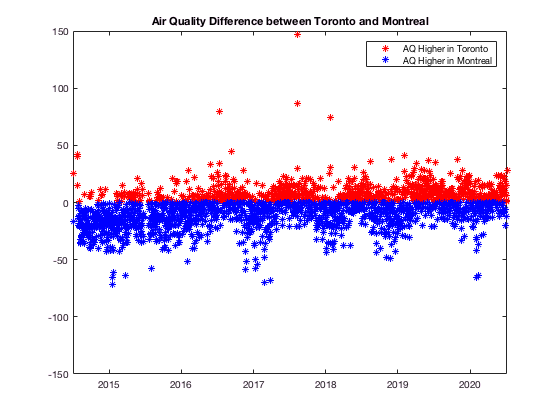


TO_Higher = zeros(length(diff), 1);
MTL_Higher = zeros(length(diff), 1);

for i = 1:length(diff)
    if diff(i)>0
        TO_Higher(i) = diff(i);
        MTL_Higher(i) = nan; 
    end 
    if diff(i)<0
        TO_Higher(i) = nan; 
        MTL_Higher(i) = diff(i);
    end 
end 

plot(TO_AQ_Table.date, TO_Higher, '*r')
hold on; 
plot(MTL_AQ_Table.date, MTL_Higher, '*b')
ylim([-150 150])
title('Air Quality Difference between Toronto and Montreal')
legend('AQ Higher in Toronto', 'AQ Higher in Montreal')

function AQ_Table = AQ_table(filename)
    % Read file into a table 
    AQ_Table = readtable(filename);
    % Create an air quality column (Max value of all columns per day)
    AQ_Col = max([AQ_Table.pm25, AQ_Table.o3, AQ_Table.no2, AQ_Table.so2, AQ_Table.co], [], 2);
    AQ_Table.AQ = AQ_Col;
    % Change dates to matlabs datetime object
    AQ_Table.date = datetime(AQ_Table.date,'InputFormat','yyyy/MM/dd');
    % Sort by date 
    [~,idx] = sort(AQ_Table.date, 'descend');
    AQ_Table = AQ_Table(idx,:);
end 

function [Table1_o Table2_o] = same_dates(Table1, Table2) 
    % Setting the length of both tables to that of the shorter table 
    max_len = min(length(Table1.date), length(Table2.date))
    Table1 = Table1(1:max_len, :);
    Table2 = Table2(1:max_len, :);
    
    % Finding all the common dates between both tables 
    [test, idx1, idx2] = intersect(Table1.date, Table2.date, 'stable');
    
    % Indexing the tables to only include common dates 
    Table1_o = Table1(idx1, :);
    Table2_o = Table2(idx2, :);

end 